xdata = [20; 30; 40; 50; 70; 90; 110; 120; 140];
ydata = [500; 385; 282; 228; 162; 122; 97; 86; 71];

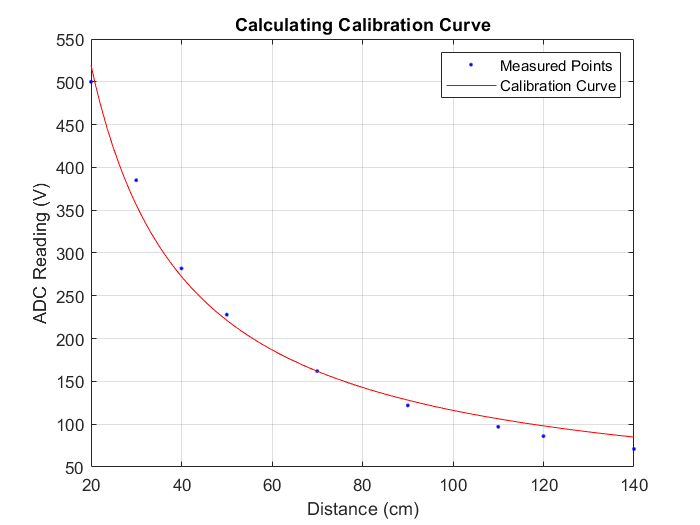

%% Fit: 'untitled fit 1'.
[xData, yData] = prepareCurveData( xdata, ydata );

% Set up fittype and options.
ft = fittype( 'power1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [6874.35073029925 -0.889096714976993];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'Measured Points', 'Calibration Curve', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
title("Calculating Calibration Curve")
xlabel( 'Distance (cm)', 'Interpreter', 'none' );
ylabel( 'ADC Reading (V)', 'Interpreter', 'none' );
grid on